clc;
clear;
% parameters
LS = 1;
dS = 0.02;
JM = 0.5;
betaM = 0.1;
R = 20;
kT = 10;
rho = 20;
kth = 1280.2;
JL = 50*JM;
betaL = 25;

% Continuous time state-space matrices
Ac = [0 1 0 0;
     -kth/JL -betaL/JL kth/(rho*JL) 0;
     0 0 0 1;
     kth/(rho*JM) 0 -kth/(rho^2*JM) -(betaM+kT^2/R)/JM];
Bc = [0 0 0 kT/(R*JM)].';
% T is Y
Cc = [kth 0 -kth/rho 0];

% Define the initial state x0
x0 = [0; 2.5; 0; 75];

% Define the sampling time
h = 0.1;

% Discretize the continuous-time system
sys = ss(Ac, Bc, Cc, 0);
sysd = c2d(sys, h);
Ad = sysd.A;
Bd = sysd.B;
Cd = sysd.C;

% Get the number of states and inputs
nx = size(Ad, 2);
nu = size(Bd, 2);

% Create the system model with the discretized matrices
model = LTISystem('A', Ad, 'B', Bd, 'C', Cd);

% Define the input constraints
umin = -200;
umax = 200;
U = Polyhedron('lb', umin, 'ub', umax);
model.u.min = umin;
model.u.max = umax;
% Define the terminal state constraints
Xf = Polyhedron('Ae', [0 1 0 0; 0 0 0 1], 'be', [0;0]);
model.x.with('terminalSet');
model.x.terminalSet = Xf;

% % Check the reachability of the initial state from the terminal set
% set flag=0,  x_range does not matter
[N, XN, K] = check_reachability(model, x0, Xf, umin, umax, 0, 0);

% Display the maximum number of steps that can be taken
fprintf('The maximum number of steps that can be taken is %d.\n', N);

The maximum number of steps that can be taken is 3.



disp(['The minimum time to reach the terminal set is ', num2str((N-1)*h), ' seconds.'])

The minimum time to reach the terminal set is 0.2 seconds.


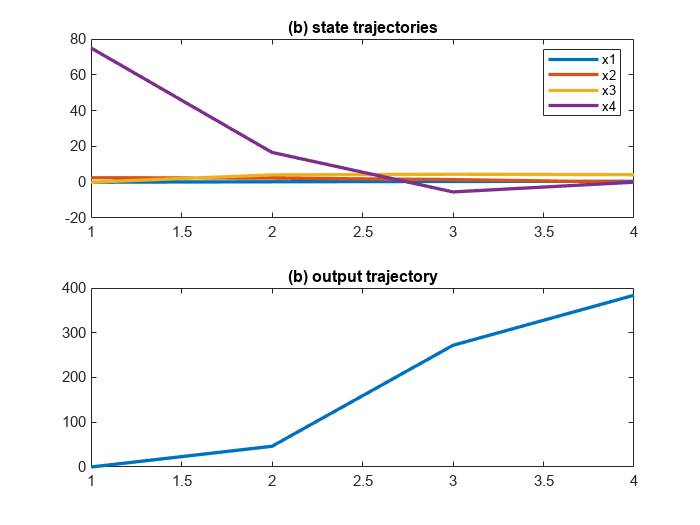


% Set initial state
initial_state = x0;
states = initial_state;
current_state = initial_state;

% Loop over the time steps
for step = 1:N
    % Get the terminal set for the current step
    terminal_set = K(N-step+1);
    
    % Update the model's terminal set
    model.x.terminalSet = terminal_set;
    
    % Create an MPC controller with the updated model
    mpc_controller = MPCController(model, 1);
    
    % Get the input value for the current state
    current_input = mpc_controller.evaluate(current_state);
    
    % Compute the next state using the current state and input
    current_state = Ad*current_state + Bd*current_input;
    
    % Append the next state to the list of states
    states(:, end+1) = current_state;
end

% Compute the output trajectories
output_matrix = [kth, 0, -kth/rho, 0] * states;

% Plot the state trajectories
figure
subplot(2,1,1)
plot(states(1,:),'LineWidth',2);
hold on
plot(states(2,:),'LineWidth',2);
plot(states(3,:),'LineWidth',2);
plot(states(4,:),'LineWidth',2);
legend('x1', 'x2', 'x3', 'x4')
title('(b) state trajectories')

% Plot the output trajectory
subplot(2,1,2)
plot(output_matrix(1,:),'LineWidth',2);
title('(b) output trajectory')

%part c
% Define the system model
model = LTISystem('A', Ad, 'B', Bd, 'C', Cd);
model.u.min = -200;
model.u.max = 200;

% Define the terminal set and the constraint set
Xf = Polyhedron('Ae', [0 1 0 0; 0 0 0 1], 'be', [0; 0]);
X = Polyhedron('A', [Cd; -Cd], 'b', [150; 150]);

% Set the terminal and constraint sets for the model
model.x.with('terminalSet');
model.x.terminalSet = Xf;
model.x.with('setConstraint');
model.x.setConstraint = X;

[N, XN, K] = check_reachability(model, x0, Xf, umin, umax, 1, X);

fprintf('The maximum number of steps that can be taken is %d.\n', N);

The maximum number of steps that can be taken is 6.



disp(['The minimum time to reach the terminal set is ', num2str((N-1)*h), ' seconds.'])

The minimum time to reach the terminal set is 0.5 seconds.


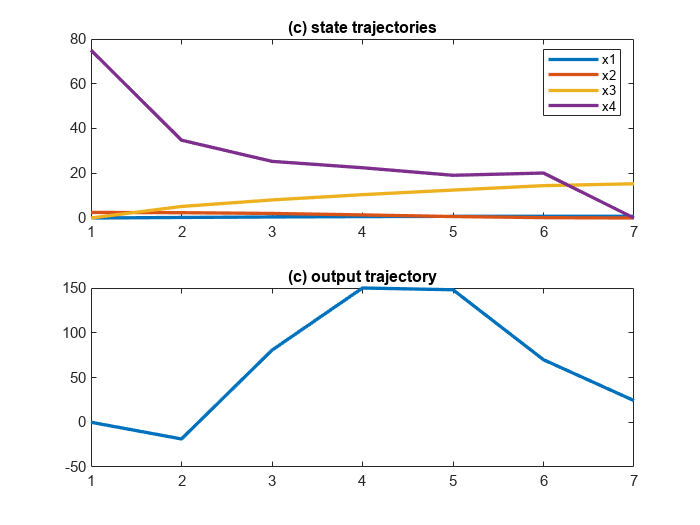


% Set initial state
pstates = x0;
current_state = x0;

% Loop over the time steps
for step = 1:N
    % Get the terminal set for the current step
    terminal_set = K(N-step+1);
    
    % Update the model's terminal set
    model.x.terminalSet = terminal_set;
    
    % Create an MPC controller with the updated model
    mpc_controller = MPCController(model, 1);
    
    % Get the input value for the current state
    current_input = mpc_controller.evaluate(current_state);
    
    % Compute the next state using the current state and input
    current_state = Ad*current_state + Bd*current_input;
    
    % Append the next state to the list of states
    pstates(:, end+1) = current_state;
end

% Compute the output trajectories
outputc = [kth, 0, -kth/rho, 0] * pstates;

% Plot the state trajectories

figure
subplot(2,1,1)
plot(pstates(1,:),'LineWidth',2);
hold on
plot(pstates(2,:),'LineWidth',2);
plot(pstates(3,:),'LineWidth',2);
plot(pstates(4,:),'LineWidth',2);
legend('x1', 'x2', 'x3', 'x4')
title('(c) state trajectories')

% Plot the output trajectory
subplot(2,1,2)
plot(outputc(1,:),'LineWidth',2);
title('(c) output trajectory')

## part d


% Define the terminal set and the constraint set
model = LTISystem('A', Ad, 'B', Bd, 'C', Cd);
model.u.min = -200;
model.u.max = 200;
lset=[10;0.01;10;0.01];
Xtarget = Polyhedron('A',[eye(4); -eye(4)],'b',[lset;lset]);
Xd = Polyhedron('A', [Cd; -Cd], 'b',[150; 150]);
% Set the terminal and constraint sets for the model
model.x.with('terminalSet');
model.x.terminalSet = Xf;
model.x.with('setConstraint');
model.x.setConstraint = Xd;

[N, XN, K] = check_reachability(model, x0, Xf, umin, umax, 1, X);

fprintf('The maximum number of steps that can be taken is %d.\n', N);

The maximum number of steps that can be taken is 6.



disp(['The minimum time to reach the terminal set is ', num2str((N-1)*h), ' seconds.'])

The minimum time to reach the terminal set is 0.5 seconds.




% Set initial state
dstates = x0;
current_state = x0;

% Loop over the time steps
for step = 1:30
    
    % Update the model's terminal set
    model.x.terminalSet = inv_set;
    
    % Create an MPC controller with the updated model
    mpc_controller = MPCController(model, 1);
    
    % Get the input value for the current state
    current_input = mpc_controller.evaluate(current_state);
    
    % Compute the next state using the current state and input
    current_state = Ad*current_state + Bd*current_input;
    
    % Append the next state to the list of states
    dstates(:, end+1) = current_state;
end

Unrecognized function or variable 'inv_set'.


% Compute the output trajectories
outputd = [kth, 0, -kth/rho, 0] * dstates;

% Plot the state trajectories

figure
plot(dstates(1,:),'LineWidth',2);
hold on
plot(dstates(2,:),'LineWidth',2);
plot(dstates(3,:),'LineWidth',2);
plot(dstates(4,:),'LineWidth',2);
legend('x1', 'x2', 'x3', 'x4')
title('(d) state trajectories')

% Plot the output trajectory
figure
plot(outputd(1,:),'LineWidth',2);
title('(d) output trajectory')



function [N, XN, K] = check_reachability(model, x0, xf_constr, umin, umax, flag, x_range)
% This function computes the reachable set of a control system and checks
% if a given initial state is contained in it.
%
% Inputs:
% - model: a control system model
% - x0: the initial state
% - xf_constr: constraints on the final state
% - umin: the lower bound on the control input
% - umax: the upper bound on the control input
% - flag: a flag indicating whether there is a limitation for the set of x
%   (1 for yes, 0 for no)
% - x_range: the set of x values that satisfy the limitation (empty for no
%   limitation)
%
% Outputs:
% - N: the number of iterations used to compute the reachable set
% - XN: the final reachable set
% - K: the sequence of reachable sets computed during the iteration


    % Initialize variables
    N = 0;
    XN = xf_constr;
    K(1) = xf_constr;

    % Compute the reachable set and check if the initial state is contained
    % in it
    while N < 100
        % Update the iteration count
        N = N + 1;

        % Compute the reachable set for the current input constraints
        XN = model.reachableSet('X', XN, 'U', Polyhedron('lb', umin, 'ub', umax), 'direction', 'backward');

        % If there is limitation for the set of x
        if flag ~= 0
            XN = XN.intersect(x_range);
        end

        % Add the current reachable set to the invariant set
        K(N+1) = XN;

        % Check if the initial state is contained in the reachable set
        if XN.contains(x0)
            break;
        end
    end

    % If the initial state is not contained in the reachable set after
    % the maximum number of iterations, display a warning
    if N == 100
        warning('The initial state may not be reachable within the maximum number of iterations.');
    end
%Remove redundant inequalities from the computed sets
for i = 1:length(K)
    K(i) = K(i).minHRep();
end
XN = XN.minHRep();

end
